clear
load('./traces/input_2.mat');

**First, calculate correlations with same operands**

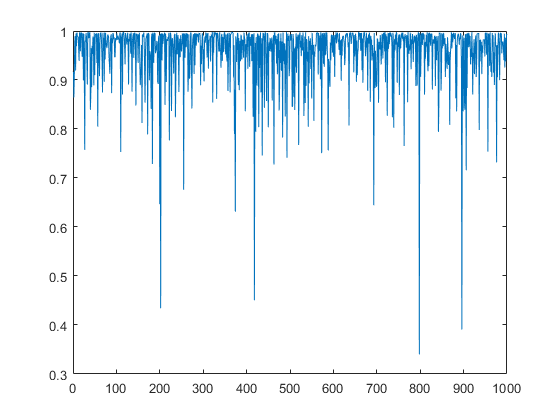

corrVec = zeros(1,1000);
for i = 2 : 1001
    corrMat = corrcoef(traces_Y(1,:),traces_Y(i,:));
    corrVec(i-1) = corrMat(1,2);
end
plot(corrVec)

Then, calculate correlations with operands inverted

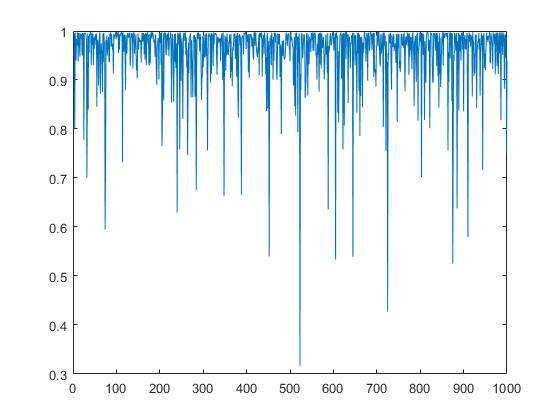

corrVec = zeros(1,1000);
for i = 1002 : 2001
    corrMat = corrcoef(traces_Y(1,:),traces_Y(i,:));
    corrVec(i-1001) = corrMat(1,2);
end
plot(corrVec)

Then, calculate correlations with second operand changed

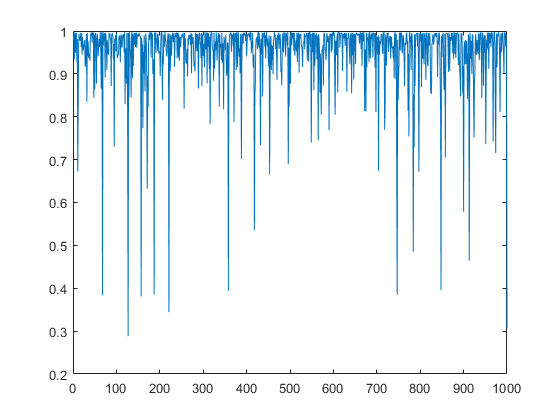

corrVec = zeros(1,1000);
for i = 2002 : 3001
    corrMat = corrcoef(traces_Y(1,:),traces_Y(i,:));
    corrVec(i-2001) = corrMat(1,2);
end
plot(corrVec)

Then, calculate correlations with first operand changed

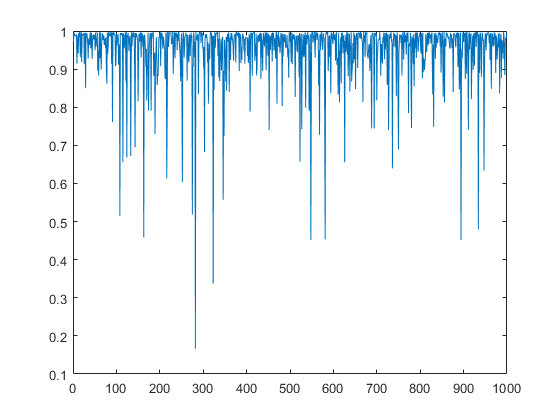

corrVec = zeros(1,1000);
for i = 3002 : 4001
    corrMat = corrcoef(traces_Y(1,:),traces_Y(i,:));
    corrVec(i-3001) = corrMat(1,2);
end
plot(corrVec)

Finally, calculate correlations with both operands changed

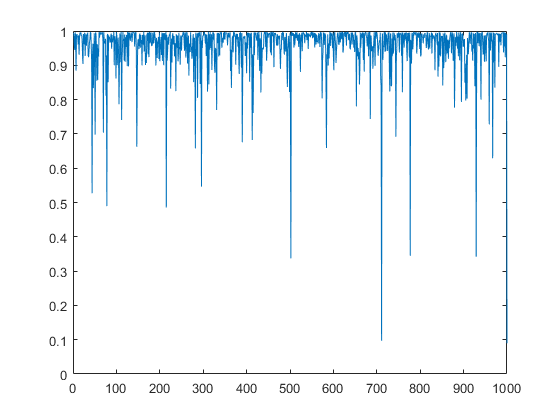

corrVec = zeros(1,1000);
for i = 4002 : 5001
    corrMat = corrcoef(traces_Y(1,:),traces_Y(i,:));
    corrVec(i-4001) = corrMat(1,2);
end
plot(corrVec)

Then average in groups of 500, calculate correlations

sameOperand = [mean(traces_Y(2:501,:),1);mean(traces_Y(502:1001,:),1)];
invertedOperand = [mean(traces_Y(1002:1501,:),1);mean(traces_Y(1502:2001,:),1)];
secondOperand = [mean(traces_Y(2002:2501,:),1);mean(traces_Y(2502:3001,:),1)];
firstOperand = [mean(traces_Y(3002:3501,:),1);mean(traces_Y(3502:4001,:),1)];
bothOperands = [mean(traces_Y(4002:4501,:),1);mean(traces_Y(4502:5001,:),1)];

disp('Correlation between two averages of operations with the same operands:');

Correlation between two averages of operations with the same operands:


corrMat = corrcoef(sameOperand(1,:),sameOperand(2,:));
corrMat(1,2)

ans =    0.999967255109978



disp('Correlation between two averages of operations with the same operands but inverted:');

Correlation between two averages of operations with the same operands but inverted:


corrMat = corrcoef(sameOperand(1,:),invertedOperand(1,:));
corrMat(1,2)

ans =    0.999858783180267


corrMat = corrcoef(sameOperand(1,:),invertedOperand(2,:));
corrMat(1,2)

ans =    0.999894597966464



disp('Correlation between two averages of operations with the same first operand:');

Correlation between two averages of operations with the same first operand:


corrMat = corrcoef(sameOperand(1,:),secondOperand(1,:));
corrMat(1,2)

ans =    0.999907452062576


corrMat = corrcoef(sameOperand(1,:),secondOperand(2,:));
corrMat(1,2)

ans =    0.999096316214613


corrMat = corrcoef(secondOperand(1,:),secondOperand(2,:));
corrMat(1,2)

ans =    0.999534496257036



disp('Correlation between two averages of operations with the same second operand:');

Correlation between two averages of operations with the same second operand:


corrMat = corrcoef(sameOperand(1,:),firstOperand(1,:));
corrMat(1,2)

ans =    0.998993435237311


corrMat = corrcoef(sameOperand(1,:),firstOperand(2,:));
corrMat(1,2)

ans =    0.999287057103306


corrMat = corrcoef(firstOperand(1,:),firstOperand(2,:));
corrMat(1,2)

ans =    0.999963632190287



disp('Correlation between two averages of operations with different operands:');

Correlation between two averages of operations with different operands:


corrMat = corrcoef(sameOperand(1,:),bothOperands(1,:));
corrMat(1,2)

ans =    0.999865661118025


corrMat = corrcoef(sameOperand(1,:),bothOperands(2,:));
corrMat(1,2)

ans =    0.999942427590226


corrMat = corrcoef(bothOperands(1,:),bothOperands(2,:));
corrMat(1,2)

ans =    0.999689116303417


No luck.

Maybe try with euclidean distance ?

disp('Euclidean distance between two averages of operations with the same operands:');

Euclidean distance between two averages of operations with the same operands:


norm(sameOperand(1,:)-sameOperand(2,:))

ans =    0.097249618521506



disp('Euclidean distance between two averages of operations with the same operands but inverted:');

Euclidean distance between two averages of operations with the same operands but inverted:


norm(sameOperand(1,:) - invertedOperand(1,:))

ans =    0.194510319470633


norm(sameOperand(1,:)-invertedOperand(2,:))

ans =    0.164262742897290



disp('Euclidean distance between two averages of operations with the same first operand:');

Euclidean distance between two averages of operations with the same first operand:


norm(sameOperand(1,:)-secondOperand(1,:))

ans =    0.158093344178078


norm(sameOperand(1,:)-secondOperand(2,:))

ans =    0.475784636918879


norm(secondOperand(1,:)-secondOperand(2,:))

ans =    0.341621660262030



disp('Euclidean distance between two averages of operations with the same second operand:');

Euclidean distance between two averages of operations with the same second operand:


norm(sameOperand(1,:)-firstOperand(1,:))

ans =    0.502094941094865


norm(sameOperand(1,:)-firstOperand(2,:))

ans =    0.422670295757135


norm(firstOperand(1,:)-firstOperand(2,:))

ans =    0.095788086690007



disp('Euclidean distance between two averages of operations with different operands:');

Euclidean distance between two averages of operations with different operands:


norm(sameOperand(1,:)-bothOperands(1,:))

ans =    0.184222871000104


norm(sameOperand(1,:)-bothOperands(2,:))

ans =    0.120457752093112


norm(bothOperands(1,:)-bothOperands(2,:))

ans =    0.279254055916629
